M = csvread(opticalFlow)

M =             0            0
          0.2            0
          0.4   0.00061469
          0.6    0.0002862
          0.8            0
            1   0.00011021
          1.2            0
          1.4            0
          1.6            0
          1.8            0


x = M(:,1)

x =             0
          0.2
          0.4
          0.6
          0.8
            1
          1.2
          1.4
          1.6
          1.8


y = M(:,2)

y =             0
            0
   0.00061469
    0.0002862
            0
   0.00011021
            0
            0
            0
            0



sOne = rms(y(1:60,:))

sOne =       0.14054


sTwo = rms(y(125:185,:))

sTwo =       0.15975


sThr = rms(y(245:285,:))

sThr =       0.14728


sFour = rms(y(365:430,:))

sFour =       0.14498



speed = string(round(rms([sOne sTwo sThr sFour]),3, 'significant'))

speed = "0.148"

speed = 'Average '  + speed

speed = "Average 0.148"

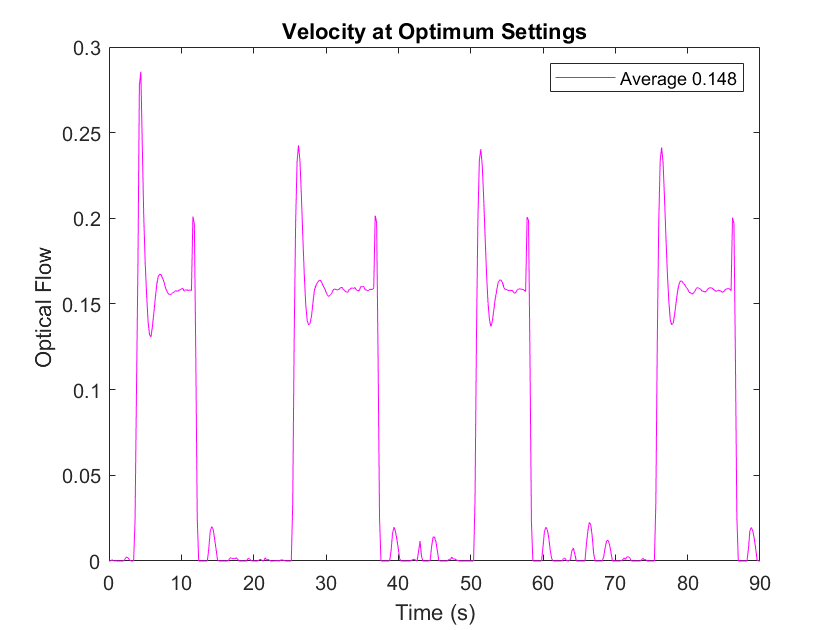


f = plot(x,y,'m');
xlabel('Time (s)');
ylabel('Optical Flow ');
title('Velocity at Optimum Settings')
legend({speed},'Location','northeast')